We start with denoising. Since its denoising the linear degradation matrix H=I (Identity). 

We first will try on a synthetic noised image. We use the imnoise which creates noise from the image itself. We also have a function getPSNR which computes the PSNR of the estimated image using the original image. 

imagename = 'cameraman256.png';
% Load noise-free image
org_img = im2double(imread(imagename));
noise=imnoise(org_img,'poisson')/4;
disp(max(noise,[],'all'));

    0.2471



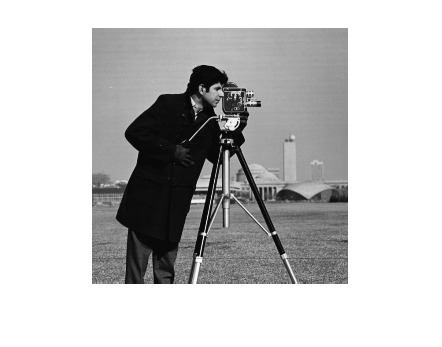

y=org_img+noise;
imshow(org_img);

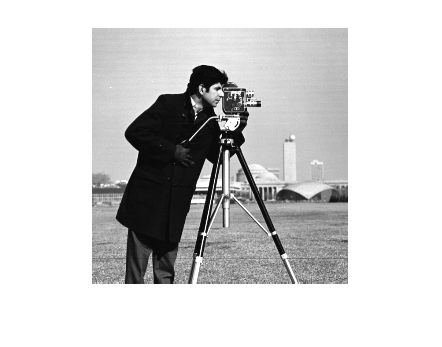

imshow(y);

%disp(rrmse(org_img,y,2));
disp(getPSNR(org_img,y));

   17.6250



The PSNR of the noisy image is 17.62 . This is since we havent added much noise.We will compare our algorithm performance with performance of a plain gaussian denoiser (BM3D)

Performance of BM3D:

Here we just use the BM3D denoiser. We are using a pre created package for effective implementation of the BM3D algorithm on black-white images.

beta=1;
epsilon=1e-3;
y_est=P4IP(y_col,beta,lambda,u_0,v_0,epsilon,size(y));

Printing the rrmse while breaking the algo    0.0069



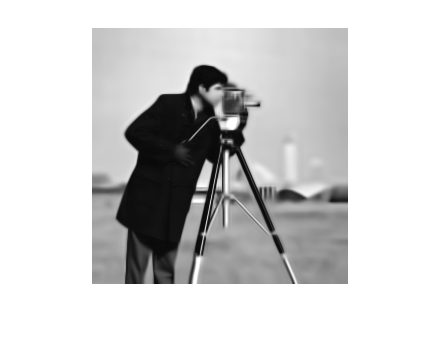

img_est=reshape(y_est,size(org_img));
figure;
imshow(img_est);

disp(getPSNR(org_img,img_est))

   17.5115



%disp(rrmse(org_img,img_est,2));

The PSNR is quite poor infact lesser than the noised image since BM3D is a gaussian denoiser but here we have poission noise.

Now we perform our algorithm of P4IP. We set lambda to be 0.25 and u to be zero initially since u = x-v and at optimal values u is zero. since we do not know the values of x we assign v as y since the denoised img will be quite similar in values with the noise image and not differ by a very large amount. Note that the weight parameter beta is a hyper parameter which must be tuned. They influence the performance quite a lot. 

y_col = y(:);
dim=size(y_col,1);
u_0=zeros(dim,1);
v_0= y(:);
lambda=0.25;

First we do a wider search over the values from 10^-5 to 10^4. If beta is very small then its like we are ignoring the gaussian denoiser. Effectively we get the noisy image itself. If the beta value is high its effectively only the BM3D algorithm. So we try to find a opt value.The precision is decided by the epsilon value. We use 1e-2 so that the execution time is faster. 

list=zeros(10,1);
epsilon=1e-2;
for i=1:10
    beta=10^(i-6);
    y_est=P4IP(y_col,beta,lambda,u_0,v_0,epsilon,size(y));
    temp=reshape(y_est,size(org_img));
    list(i)=getPSNR(org_img,temp);
end

Printing the rrmse while breaking the algo    0.0018

Printing the rrmse while breaking the algo    0.0037

Printing the rrmse while breaking the algo    0.0064

Printing the rrmse while breaking the algo    0.0074

Printing the rrmse while breaking the algo    0.0076

Printing the rrmse while breaking the algo    0.0089

Printing the rrmse while breaking the algo    0.0098

Printing the rrmse while breaking the algo    0.0159

Printing the rrmse while breaking the algo    0.0165

Printing the rrmse while breaking the algo    0.0086



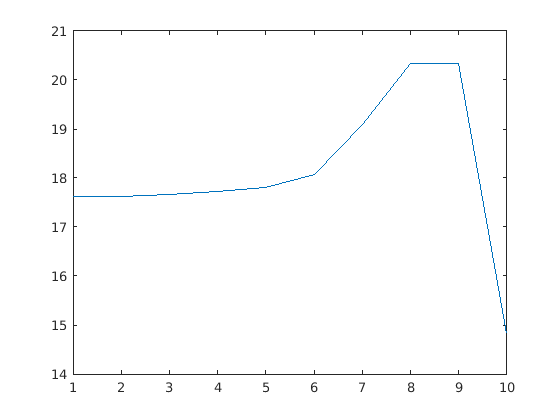

figure
plot(1:10,list);

We find that using beta around 1e2 gives a good performance. So now again we do a smaller search between 1e2 and 1e3. The change in PSMR isnt much so we can stop. The opt value is around 400. 

list=zeros(10,1);
epsilon=1e-2;
for i=1:10
    beta=i*10^(8-6);
    y_est=P4IP(y_col,beta,lambda,u_0,v_0,epsilon,size(y));
    temp=reshape(y_est,size(org_img));
    list(i)=getPSNR(org_img,temp);
end

Printing the rrmse while breaking the algo    0.0159

Printing the rrmse while breaking the algo    0.0173

Printing the rrmse while breaking the algo    0.0196

Printing the rrmse while breaking the algo    0.0199

Printing the rrmse while breaking the algo    0.0171

Printing the rrmse while breaking the algo    0.0196

Printing the rrmse while breaking the algo    0.0169

Printing the rrmse while breaking the algo    0.0167

Printing the rrmse while breaking the algo    0.0147

Printing the rrmse while breaking the algo    0.0165



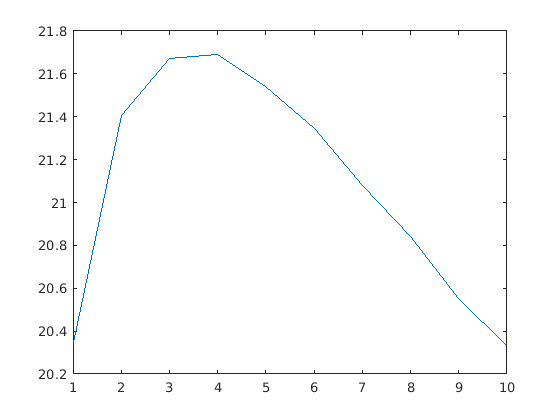

figure
plot(1:10,list);

We now show the difference it peformance between different epsilon value for the good value of beta

y_est=P4IP(y_col,400,lambda,u_0,v_0,1,size(y));

Printing the rrmse while breaking the algo    0.2959



temp=reshape(y_est,size(org_img));
disp(getPSNR(org_img,temp));

   17.6250




y_est=P4IP(y_col,400,lambda,u_0,v_0,0.1,size(y));

Printing the rrmse while breaking the algo    0.0282



temp=reshape(y_est,size(org_img));
disp(getPSNR(org_img,temp));

   31.8199




y_est=P4IP(y_col,400,lambda,u_0,v_0,1e-3,size(y));

Printing the rrmse while breaking the algo    0.0199



temp=reshape(y_est,size(org_img));
disp(getPSNR(org_img,temp));

   21.6886



variance= var(noise,0,'all');
% Call BM3D With the default settings.
est = BM3D(y, sqrt(variance));
imshow(est);
disp(getPSNR(org_img,est));
%disp(rrmse(org_img,est,2));

y_est=P4IP(y_col,20,lambda,u_0,v_0,0.1,size(y));

Printing the rrmse while breaking the algo    0.0328



temp=reshape(y_est,size(org_img));
disp(getPSNR(org_img,temp));

   22.0176

